# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 07-Jan-2024 22:16:25

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 40);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["time", "time_normalized", "TrunkAngle", "HipAngle", "KneeAngle", "AnkleAngle", "Red1_Raw_0_X", "Red1_Raw_0_Y", "Green_Raw_0_X", "Green_Raw_0_Y", "Blue1_Raw_0_X", "Blue1_Raw_0_Y", "Red2_Raw_0_X", "Red2_Raw_0_Y", "Blue2_Raw_0_X", "Blue2_Raw_0_Y", "MOI_InitialContact", "MOI_InitialContact_ScoreValue", "MOI_InitialContact_ScoreText", "MOI_LoadingResponse", "MOI_LoadingResponse_ScoreValue", "MOI_LoadingResponse_ScoreText", "MOI_MidStance", "MOI_MidStance_ScoreValue", "MOI_MidStance_ScoreText", "MOI_TerminalStance", "MOI_TerminalStance_ScoreValue", "MOI_TerminalStance_ScoreText", "MOI_PreSwing", "MOI_PreSwing_ScoreValue", "MOI_PreSwing_ScoreText", "MOI_InitialSwing", "MOI_InitialSwing_ScoreValue", "MOI_InitialSwing_ScoreText", "MOI_MidSwing", "MOI_MidSwing_ScoreValue", "MOI_MidSwing_ScoreText", "MOI_TerminalSwing", "MOI_TerminalSwing_ScoreValue", "MOI_TerminalSwing_ScoreText"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["MOI_InitialContact", "MOI_InitialContact_ScoreValue", "MOI_InitialContact_ScoreText", "MOI_LoadingResponse", "MOI_LoadingResponse_ScoreValue", "MOI_LoadingResponse_ScoreText", "MOI_MidStance", "MOI_MidStance_ScoreValue", "MOI_MidStance_ScoreText", "MOI_TerminalStance", "MOI_TerminalStance_ScoreValue", "MOI_TerminalStance_ScoreText", "MOI_PreSwing", "MOI_PreSwing_ScoreValue", "MOI_PreSwing_ScoreText", "MOI_InitialSwing", "MOI_InitialSwing_ScoreValue", "MOI_InitialSwing_ScoreText", "MOI_MidSwing", "MOI_MidSwing_ScoreValue", "MOI_MidSwing_ScoreText", "MOI_TerminalSwing", "MOI_TerminalSwing_ScoreValue", "MOI_TerminalSwing_ScoreText"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["MOI_InitialContact", "MOI_InitialContact_ScoreValue", "MOI_InitialContact_ScoreText", "MOI_LoadingResponse", "MOI_LoadingResponse_ScoreValue", "MOI_LoadingResponse_ScoreText", "MOI_MidStance", "MOI_MidStance_ScoreValue", "MOI_MidStance_ScoreText", "MOI_TerminalStance", "MOI_TerminalStance_ScoreValue", "MOI_TerminalStance_ScoreText", "MOI_PreSwing", "MOI_PreSwing_ScoreValue", "MOI_PreSwing_ScoreText", "MOI_InitialSwing", "MOI_InitialSwing_ScoreValue", "MOI_InitialSwing_ScoreText", "MOI_MidSwing", "MOI_MidSwing_ScoreValue", "MOI_MidSwing_ScoreText", "MOI_TerminalSwing", "MOI_TerminalSwing_ScoreValue", "MOI_TerminalSwing_ScoreText"], "EmptyFieldRule", "auto");

% Import the data
Eleora3_1 = readtable("E:\ \DOCUMENTS\2023 Project\kone\training\27\c2\Eleora3.1.csv", opts)

Eleora3_1 = 62×40 table
     time     time_normalized    TrunkAngle    HipAngle    KneeAngle    AnkleAngle    Red1_Raw_0_X    Red1_Raw_0_Y    Green_Raw_0_X    Green_Raw_0_Y    Blue1_Raw_0_X    Blue1_Raw_0_Y    Red2_Raw_0_X    Red2_Raw_0_Y    Blue2_Raw_0_X    Blue2_Raw_0_Y    MOI_InitialContact    MOI_InitialContact_ScoreValue    MOI_InitialContact_ScoreText    MOI_LoadingResponse    MOI_LoadingResponse_ScoreValue    MOI_LoadingResponse_ScoreText    MOI_MidStance    MOI_MidStance_ScoreValue    MOI_MidStance_ScoreText    MOI_TerminalStance    MOI

## Clear temporary variables

clear opts


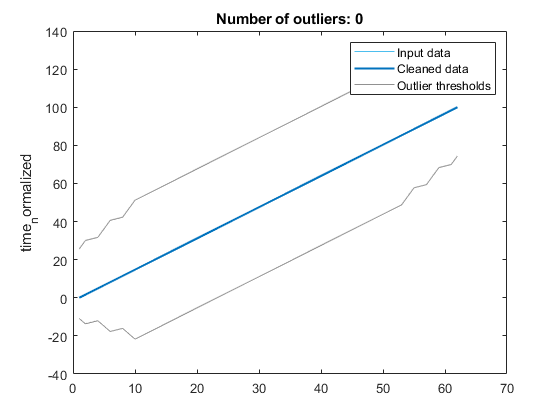

% Fill outliers
[newEleora3_1,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(Eleora3_1,...
    "linear","movmedian",19,"DataVariables",["time_normalized","HipAngle"]);

% Display results
clf
plot(Eleora3_1.time_normalized,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(newEleora3_1.time_normalized,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices(:,2)),Eleora3_1.time_normalized(outlierIndices(:,2)),...
    "x","Color",[64 64 64]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices(:,2)))

% Plot filled outliers
plot(find(outlierIndices(:,2)),newEleora3_1.time_normalized(outlierIndices(:,2)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([(1:numel(Eleora3_1.time_normalized))'; missing; (1:numel(Eleora3_1.time_normalized))'],...
    [thresholdHigh.time_normalized(:); missing; thresholdLow.time_normalized(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend
ylabel("time_normalized")

clear outlierIndices thresholdLow thresholdHigh

## `Normalize`

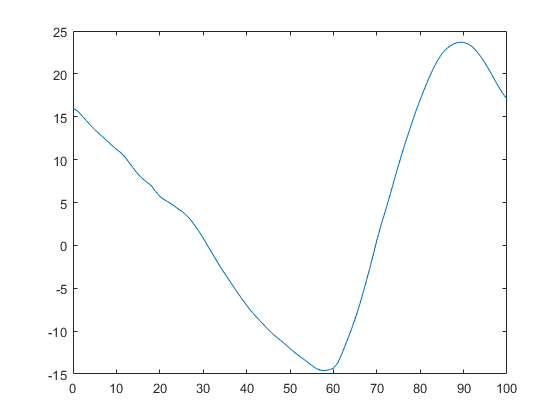

x=newEleora3_1.time_normalized;
y=newEleora3_1.HipAngle;
i=0:1:100;
s = spline(x,y,i);
figure
plot(0:100,s)

## `Smoothening`

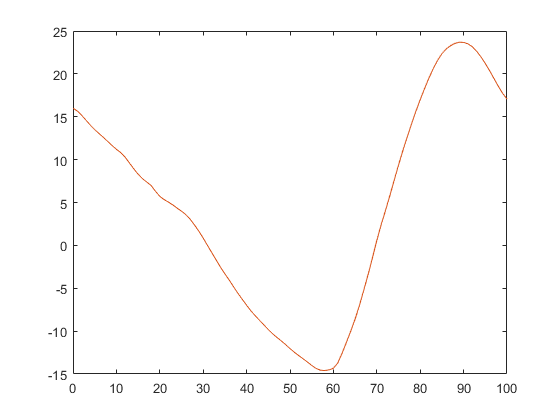

u = smooth(0:100, s, 0.01, 'rloess'); hold on;
plot(0:100,u)

v=diff(u)./diff(0:100);
a=diff(v)./diff(0:100);